clc;
clear all;
close all;

#### IRs from empty room

% Reference room I: dataI_...
               % s1r1 source position 1 and receiver position 1
               % s2r1 source position 2 and receiver position 1
               % s1r2 source position 1 and receiver position 2
% Reference room II: dataII_...
% Reference room III: dataIII_measured

#### IRs from furnished room

% Test room A: dataA_...
% Test room B: dataB_...           
% Test room C: dataC_...  
               % m1 represent absorption coefficient of furniture is 0.1
               % m2 represent absorption coefficient of furniture is 0.3
               % m3 represent absorption coefficient of furniture is 0.5
% Test room D: dataD_...
% Test room E: dataE_...
% Test room F: datad_measured

#### Loading Data

folders=addpath('ESC_functions','data');

Choose simluated data

% measuredData= false;
% load('dataI_s1r1.mat');
% IRwithoutFilter(:,:,1)=data;
% load('dataC_s1r1m2.mat');
% IRwithoutFilter(:,:,2)=data;

Choose measured data

measuredData= true;
load('dataIII_measured.mat');
IRwithoutFilter(:,:,1)=data;
load('dataF_measured.mat');
IRwithoutFilter(:,:,2)=data;

#### To plot

% Which 1/3 octave band to plot
plotOctaveBand=9;
% which receiver to plot
plotReceiver=1;

#### Basic parameters

% Number of the scenarios
nScenarios=size(IRwithoutFilter,3);
% Speed of sound (m/s)
c0 = 343;
% Length of the signals
nSamplesSignal=length(data);
% Sampling frequency (Hz)
fs = nSamplesSignal-1;
% Time vector
tv = (0:1:nSamplesSignal-1) * (1 / fs);
% Max frequency
fMax=2500;

#### Equation to calculate sound pressure level

spl = @(input)(20 * log10(abs(input)))+120;

#### Transducers

% Number of receivers
nReceivers = length(receiverPos);
% Distance from source to receivers
distance = vecnorm(abs(bsxfun(@minus,sourcePos,receiverPos))')';
% Calculate arrival time (s)
tDirectSec = distance ./ c0;
% Calculate arrival time (sampleNo)
nDirectSample = ceil(tDirectSec*fs);

#### To define time window (to chop signals)

meanFreePathLength = 4 * volume ./ surfaceArea;
% Approximate reflection order
order = (1./meanFreePathLength)*tv * c0 ;
% Each short signal contains one reflection 
nReflection = 1;
% Number of short signals
tMax =max(tv);
nSegment = floor(tMax/(nReflection * (meanFreePathLength/ c0)));
% Points of each short signal contains
nChoppedIR = floor(nSamplesSignal/nSegment);
% Time vector for each short signal
tSegment=nChoppedIR*(0.5:nSegment-0.5)/fs;
% Length of each segment
dSegment=nChoppedIR/fs;

#### Wide Band (20 to highest frequency) reverberation time 

for iScenario = 1:nScenarios
for iReceiver = 1:nReceivers
 [~,~,thisfullBandT30,~] = calculate_reverbtime(measuredData,nDirectSample(iReceiver), IRwithoutFilter(:,iReceiver,iScenario), nSamplesSignal,tv);
% Wide band reverberation time
fullBandT30(iScenario,iReceiver,:)=thisfullBandT30;
end
end
averagedfullBandT30=mean(fullBandT30,2)% Spatial averaging T30

averagedfullBandT30 =     1.3689
    1.2867


tPlot=min(averagedfullBandT30(1),1);
schroederFrequency = (0.33 * (averagedfullBandT30 * c0.^3 / volume).^0.5)% Schroeder frequency (Hz)

schroederFrequency =   287.5958
  278.8273


#### To define filter

% Center frequency of the filter 
centerFrequenciesValid=[315  400  500    630    800   1000   1250    1600   2000];% or use centerFrequencies=getCenterFrequencies(ofb);
% Number of 1/3 octave bands 
nOctaveBands=length(centerFrequenciesValid);
% Filter    
ofb = octaveFilterBank("1/3 octave",fs,FilterOrder=10);
bandpassFilters = freqz(ofb,NFFT=fs/2+1); 
bandpassFiltersValid=abs(bandpassFilters(:,12:20));

#### To filter IRs

for iScenario = 1:nScenarios
for iReceiver = 1:nReceivers
for iOctaveBand = 1:nOctaveBands        
         thisIRfiltered=calculate_filteredSignal(IRwithoutFilter(:,iReceiver,iScenario),bandpassFiltersValid(:,iOctaveBand),nSamplesSignal);
         IRfiltered(iScenario,iReceiver,iOctaveBand,:)=thisIRfiltered;
end 
end
end

#### To chop signals

% Max order of the short signal
maxOrder=10;
% Order vector
nOrder=0:maxOrder;
% To chop signals using a rectangular window
choppedIRs=cat(4,reshape(IRfiltered(:,:,:,1:(maxOrder+1)*nChoppedIR),nScenarios,nReceivers,nOctaveBands,nChoppedIR,(maxOrder+1)),zeros(nScenarios,nReceivers,nOctaveBands,fs/10-nChoppedIR,maxOrder+1));
% Frequency resolution of the chopped signal
resFrequency=1/(length(choppedIRs)/fs);
% Number of frequency points
nFrequency=fMax/resFrequency+1;
% Frequency vector of the chopped signal
fChopped=0:resFrequency:(nFrequency-1)*resFrequency;
% Fourier Transform 
choppedSTFs=fft(choppedIRs,[],4)/(fs/10);% symmetric transfer function
choppedTFs=choppedSTFs(:,:,:,1:nFrequency,:);% single side transfer function

## Equivalent Scattering Coefficients (ESCs)

#### To calculate coherence

% Transfer function for empty room
Fx=choppedTFs(1,:,:,:,:,:);
% Transfer function for furnished room
Fy=choppedTFs(2,:,:,:,:,:);
% Power spectral densities
Sxx = (abs(Fx)).^2;
Syy = (abs(Fy)).^2;
% Cross power spectral densities
Sxy = Fx .* conj(Fy);
% To calculate coherence
SXX = abs(mean(Sxx, 2));
SYY = abs(mean(Syy, 2));
SXY = abs(mean(Sxy, 2));
coherenceCoefsAllFrequency = SXY./((SXX .* SYY).^0.5);
% Frequency averaged
coherenceCoefs=reshape(mean(coherenceCoefsAllFrequency,4),nOctaveBands,(maxOrder+1));

#### To extract ESCs

for iOctaveBand=1:nOctaveBands
for iScatteringCoef=1:1000
    % Estimated ESCs from 0 to 1
    thisScatteringCoef=0.001*iScatteringCoef; 
    % Calculated coherence curve using the estimated ESCs
    thiscoherenceCurve=[((1 -thisScatteringCoef).^(nOrder(1:maxOrder+1))).^0.5];
    % Calculate the difference between real and estimated coherence curves
    deltaCoherenceCurve(iScatteringCoef,:)=sum(abs(thiscoherenceCurve-coherenceCoefs(iOctaveBand,:)).^2);
end
% Find the best fitted value of ESC
ESC(iOctaveBand)=0.001*(find(deltaCoherenceCurve==min(deltaCoherenceCurve))); 
% To analyze the effects of ESCs, ESCs can be adjusted by: 
% ESC(iOctaveBand)=0.5;
% Coherence curves until 10th order
predictedCoherenceCurve(iOctaveBand,:)  =  [((1 -  ESC(iOctaveBand)).^nOrder(1:maxOrder+1)).^0.5];
% Coherence envelope
coherentEnvelope(iOctaveBand,:)  =  [ones(1,nChoppedIR),((1 -  ESC(iOctaveBand)).^order(1:end-nChoppedIR)).^0.5]; %[((1 -  ESC(iOctaveBand)).^order).^0.5]; 
% Incoherence envelope
incoherentEnvelope(iOctaveBand,:) = (1-(coherentEnvelope(iOctaveBand,:)).^2).^0.5;
end

#### Plot ESC

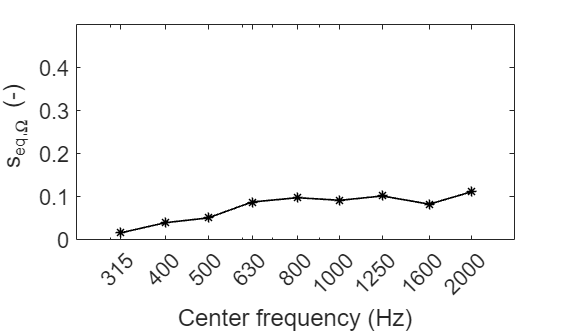

figure;
plot(centerFrequenciesValid, ESC, "k*-", 'LineWidth', 1)
set(gca,'XScale','log');
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');ylabel(' s_{eq,\Omega} (-)');
plot_figures(250,2500,0,0.5)

#### Plot coherence coefficent curves

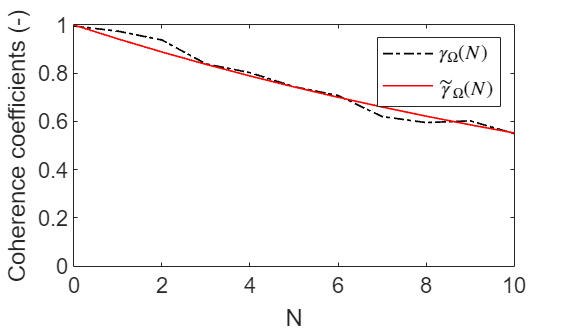

figure;
plot(nOrder,coherenceCoefs(plotOctaveBand,:),"k-.",'LineWidth',1);
hold on;
plot(nOrder,predictedCoherenceCurve(plotOctaveBand,:),"r",'LineWidth',1);
legend({'$\gamma_{\Omega}(N)$','$\tilde{\gamma}_{\Omega}(N)$'}, 'Interpreter', 'latex');
xlabel('N');ylabel('Coherence coefficients (-)');
plot_figures(0,10,0,1)

#### Decay curve for 1/3 octave bands

for iScenario = 1:nScenarios
for iReceiver = 1:nReceivers
for iOctaveBand = 1:nOctaveBands
 [~,~,~,thisDecayCurvefitted] = calculate_reverbtime(measuredData,nDirectSample(iReceiver), IRfiltered(iScenario,iReceiver,iOctaveBand,:), nSamplesSignal,tv);
decayCurvesfitted(iScenario,iReceiver,iOctaveBand,:)=thisDecayCurvefitted;
end
end
end
% Spatial averaged values (Pa)
averagedDecayCurvesfitted=reshape(mean(10.^((decayCurvesfitted-120)/20),2),nScenarios,nOctaveBands,[]);
% Spatial averaged values (dB)
averagedDecayCurvesfittedSPL=spl(averagedDecayCurvesfitted);

#### Absorption Envelope

For measured data, the decay curve is linear

if  measuredData == true

for iScenario = 1:nScenarios
for iOctaveBand=1:nOctaveBands
% decay curve
thisaveragedDecayCurvesfitted=reshape(averagedDecayCurvesfittedSPL(iScenario,iOctaveBand,:),1,[]);
p = polyfit(tv,thisaveragedDecayCurvesfitted,1);
averagedT60=60/(-p(1));
% absorption Coefficients
absorptionCoef= (1 - exp(log(10^-6)*meanFreePathLength./(averagedT60 * c0 )));
% Absorption Envelope
absorptionEnv(iScenario,iOctaveBand,:) = ((1 - absorptionCoef).^(order)).^0.5;
end
end

For simulated data, the decay curve is not linear

else 
for iScenario = 1:nScenarios
for iOctaveBand=1:nOctaveBands
% decay curve
thisaveragedDecayCurvesfitted=reshape(averagedDecayCurvesfitted(iScenario,iOctaveBand,:),1,[]);
% Absorption Envelope
absorptionEnv(iScenario,iOctaveBand,:)=thisaveragedDecayCurvesfitted/max(thisaveragedDecayCurvesfitted);
end
end

end

#### To find the magnitude for the envelopes

% Saptial averaged IRs
IRfiltered_SaptialAverage=reshape(mean((abs(IRfiltered(1,:,:,1:fs/2))).^2,2),nOctaveBands,[]);
% Calculate energy of IRs
IRfiltered_energy=sum(IRfiltered_SaptialAverage,2);
% Calculate energy of envelopes
absorptionEnvelope_Energy=sum(absorptionEnv(1,:,1:fs/2).^2,3)';
% To find the magnitude for the envelopes make the energy of the envelopes
% same with energy of IRs
envMagnitude=(IRfiltered_energy./absorptionEnvelope_Energy).^0.5';
% Apply this magnitude in absorption envelope
absorptionEnvScaled=reshape(envMagnitude,1,9,1).*absorptionEnv;

#### Plot IR and absorption envelope  [FIG.11(a)]

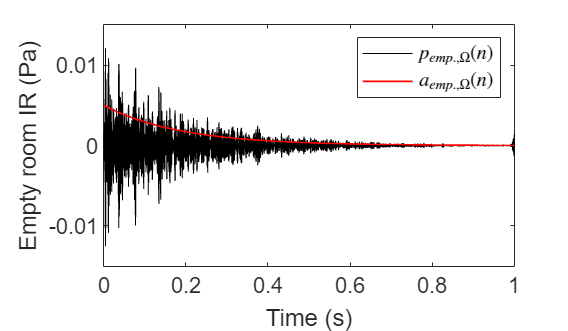

figure;
plot(tv,reshape(IRfiltered(1,plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.1);
hold on;
plot(tv,reshape(absorptionEnvScaled(1,plotOctaveBand,:),1,[]),"r",'LineWidth',1);
legend('${{p}_{emp.,\Omega}}(n)$','${a}_{emp.,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Empty room IR (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot absorption envelopes of empty room and furnished room                 

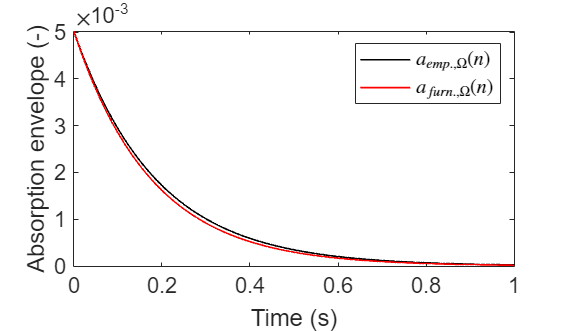

figure
plot(tv,reshape(absorptionEnvScaled(1,plotOctaveBand,:),1,[]),"k",'LineWidth',1);
hold on
plot(tv,reshape(absorptionEnvScaled(2,plotOctaveBand,:),1,[]),"r",'LineWidth',1);
legend('${a}_{emp.,\Omega}(n)$','${a}_{furn.,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Absorption envelope (-)');
plot_figures(0,tPlot,0, envMagnitude(plotOctaveBand))

#### Eliminate the impact of absorption 

absorptionCorrection=reshape(absorptionEnv(2,:,:)./absorptionEnv(1,:,:),nOctaveBands,[]);

#### Specular and non-specular envelopes

specularEnvelope = coherentEnvelope.* reshape(absorptionEnvScaled(2,:,:),nOctaveBands,[]);
nonspecularEnvelope = incoherentEnvelope.* reshape(absorptionEnvScaled(2,:,:),nOctaveBands,[]);

#### Plot specular and non-specular envelopes             [FIG.11(b)]

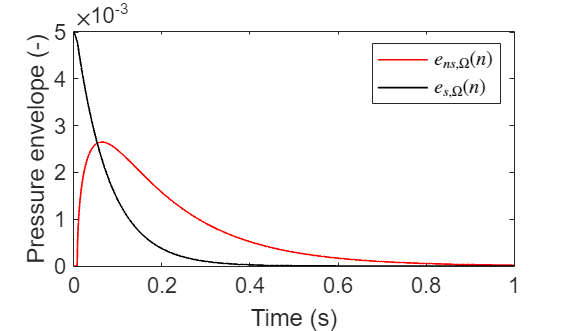

figure;
plot(tv,nonspecularEnvelope(plotOctaveBand,:),"r",'LineWidth',1)
hold on
plot(tv,specularEnvelope(plotOctaveBand,:),"k",'LineWidth',1)
legend('${e}_{ns,\Omega}(n)$','${e}_{s,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Pressure envelope (-)');
plot_figures(0,tPlot,0, envMagnitude(plotOctaveBand))

## Hybrid model

for iReceiver = 1:nReceivers
for iOctaveBand = 1:nOctaveBands
%  IRs of empty room corrected by absorption 
IRfilteredEmptyCorrected =reshape(IRfiltered(1,iReceiver,iOctaveBand,:),1,[]).*absorptionCorrection(iOctaveBand,:);
%  IRs of furnished room
IRfilteredFurnished = reshape(IRfiltered(2,iReceiver,iOctaveBand,:),1,[]);
% Specular part
thisSpecularPart = IRfilteredEmptyCorrected .* coherentEnvelope(iOctaveBand,:);
% Non-specular part generated by noise
noise = (3^0.5)*(2 * rand(1, nSamplesSignal) - 1);
noiseFiltered=calculate_filteredSignal(noise',bandpassFiltersValid(:,iOctaveBand),nSamplesSignal);
% Make the energy (stand deviation) of this noise into 1
thisNoiseCorrection = ((sum((abs(noise)).^2) / sum((abs(noiseFiltered)).^2)))^0.5;
% Or use: thisNoiseCorrection=1/((mean((abs(noiseFiltered)).^2)).^0.5);
thisNoiseFilteredCorrected = thisNoiseCorrection * noiseFiltered;
thisNonSpecularPartPredicted = (thisNoiseFilteredCorrected' .* nonspecularEnvelope(iOctaveBand,:));
%  Predicted Furnished room IRs
thisIRfilteredPredicted = thisNonSpecularPartPredicted + thisSpecularPart;
%  Store data in matrix
specularPart(iReceiver,iOctaveBand, :)=thisSpecularPart;
nonspecularPartTruth(iReceiver,iOctaveBand, :)=IRfilteredFurnished - thisSpecularPart;
nonspecularPartPredicted(iReceiver,iOctaveBand, :)=thisNonSpecularPartPredicted;
IRfilteredFurnishedPredicted(iReceiver,iOctaveBand, :)=thisIRfilteredPredicted;
end
end

#### Plot specular part             [FIG.11(c)]

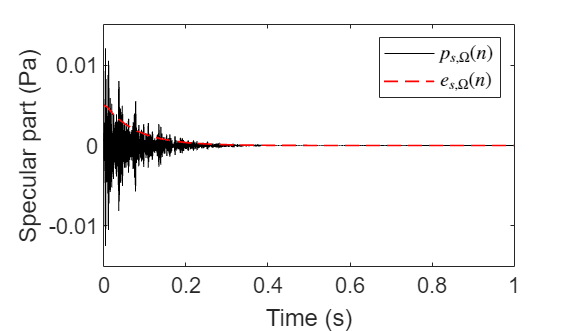

figure;
plot(tv,reshape(specularPart(plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.1);
hold on
plot(tv,specularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
legend('${{p}_{s,\Omega}}(n)$','${e}_{s,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Specular part (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot real non-specular part 

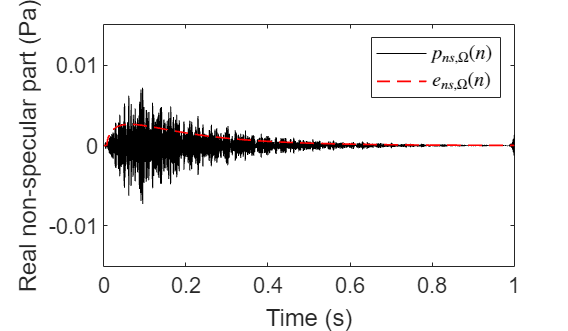

figure;
plot(tv,reshape(nonspecularPartTruth(plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.1);
hold on
plot(tv,nonspecularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
legend('${{p}_{ns,\Omega}}(n)$','${e}_{ns,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Real non-specular part (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot generated non-specular part         [FIG.11(d)]

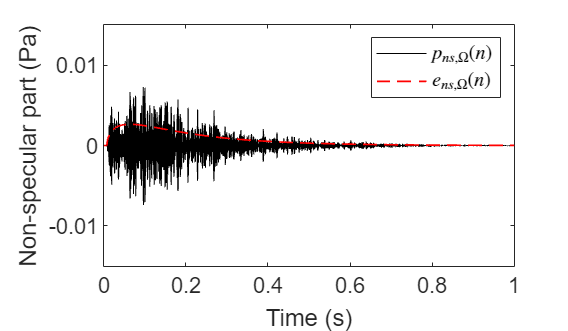

figure;
plot(tv,reshape(nonspecularPartPredicted(plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.1);
hold on
plot(tv,nonspecularEnvelope(plotOctaveBand,:),"r--",'LineWidth',1)
legend('${{p}_{ns,\Omega}}(n)$','${e}_{ns,\Omega}(n)$', 'Interpreter', 'latex')
xlabel('Time (s)');ylabel('Non-specular part (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot IR (Pa) of 1/3 octave bands                [FIG.4]

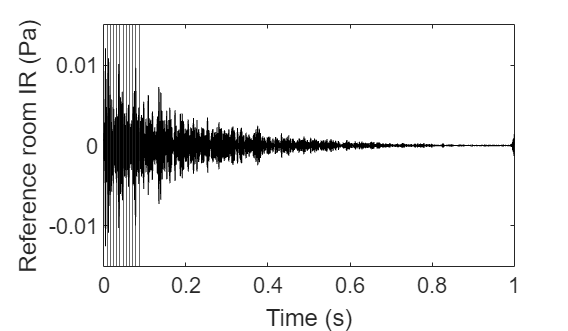

% IR of empty room
figure;
for iSegment=1:maxOrder+1
    hold on
    xline(iSegment*nChoppedIR/fs,'LineWidth',0.3)
end
plot(tv,reshape(IRfiltered(1,plotReceiver,plotOctaveBand,:),1,[]),"k",'LineWidth',0.1);
xlabel('Time (s)');ylabel( 'Reference room IR (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

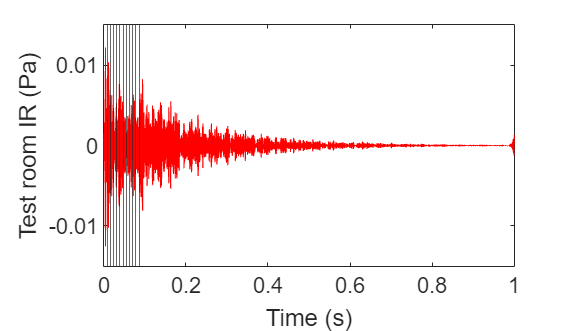

% Ground truth IR of furnished room
figure;
for iSegment=1:maxOrder+1
    hold on
    xline(iSegment*nChoppedIR/fs,'LineWidth',0.3)
end
hold on
plot(tv,reshape(IRfiltered(2,plotReceiver,plotOctaveBand,:),1,[]),"r",'LineWidth',0.1);
xlabel('Time (s)');ylabel( 'Test room IR (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

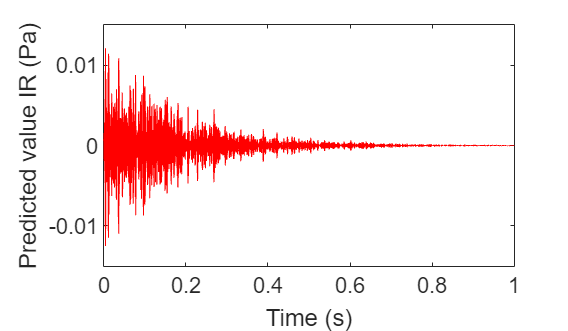

% Predicted IR of furnished room
figure;
plot(tv,reshape(IRfilteredFurnishedPredicted(plotReceiver,plotOctaveBand,:),1,[]),"r",'LineWidth',0.1);
xlabel('Time (s)');ylabel('Predicted value IR (Pa)');
plot_figures(0,tPlot,-envMagnitude(plotOctaveBand)*3, envMagnitude(plotOctaveBand)*3)

#### Plot IR (dB) of 1/3 octave bands              [FIG.12]

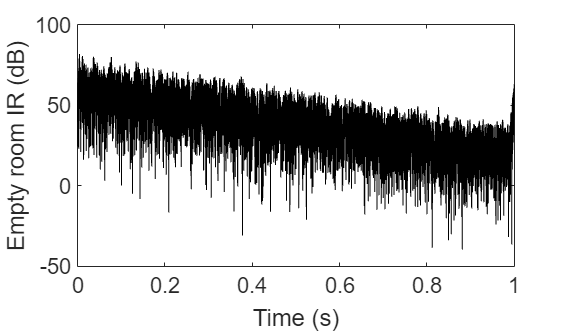

%  IR of reference room
figure;
plot(tv,spl(reshape(IRfiltered(1,plotReceiver,plotOctaveBand,:),1,[])),"k",'LineWidth',0.1);
xlabel('Time (s)');ylabel('Empty room IR (dB)');
plot_figures(0,tPlot,-50, 100)

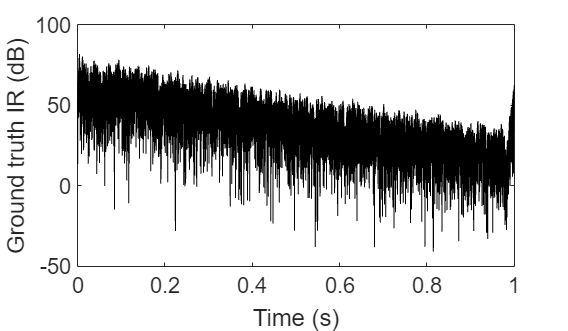

% Ground truth IR of furnished room
figure;
plot(tv,spl(reshape(IRfiltered(2,plotReceiver,plotOctaveBand,:),1,[])),"k",'LineWidth',0.1);
% hold on
% plot(tv,reshape(spl(3^0.5*absorptionEnvelope(2,plotOctaveBand,:)),1,[]),'color',[.5 .5 .5],'LineWidth',1)
xlabel('Time (s)');ylabel('Ground truth IR (dB)');
plot_figures(0,tPlot,-50, 100)

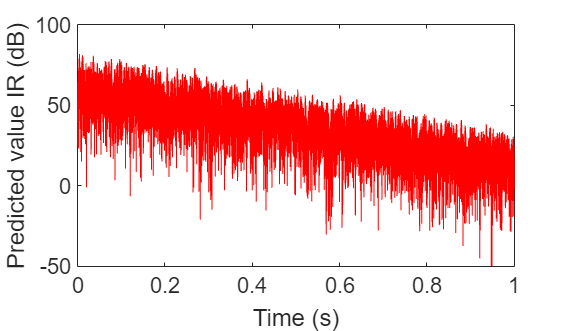

% Predicted IR of furnished room
figure
plot(tv,spl(reshape(IRfilteredFurnishedPredicted(plotReceiver,plotOctaveBand,:),1,[])),"r",'LineWidth',0.1);
% hold on
% plot(tv,reshape(spl(3^0.5*absorptionEnvelope(2,plotOctaveBand,:)),1,[]),'color',[.5 .5 .5],'LineWidth',1)
xlabel('Time (s)');ylabel('Predicted value IR (dB)');
plot_figures(0,tPlot,-50, 100)

## Evaluation

for iReceiver = 1:nReceivers
% Index for direct sound
nStart=nDirectSample(iReceiver);
for iOctaveBand = 1:nOctaveBands
% Ground truth IR
thisIRfilteredFurnishedTruth = reshape(IRfiltered(2,iReceiver,iOctaveBand,:),1,[]);
[thisEDTTruth,thisT20Truth,thisT30Truth,~] = calculate_reverbtime(measuredData,nStart, thisIRfilteredFurnishedTruth, nSamplesSignal,tv);
thisEnergyTruth=calculate_energy(thisIRfilteredFurnishedTruth);
% Store data in matrix
EDTTruth(iReceiver,iOctaveBand,:)=thisEDTTruth;
T20Truth(iReceiver,iOctaveBand,:)=thisT20Truth;
T30Truth(iReceiver,iOctaveBand,:)=thisT30Truth;
EnergyTruth(iReceiver,iOctaveBand,:)=thisEnergyTruth;
% Predicted IR
thisIRfilteredPredicted=reshape(IRfilteredFurnishedPredicted(iReceiver,iOctaveBand,:),1,[]);
[thisEDTPredicted,thisT20Predicted,thisT30Predicted,~] = calculate_reverbtime(measuredData, nStart, thisIRfilteredPredicted, nSamplesSignal,tv);
thisEnergyPredicted=calculate_energy(thisIRfilteredPredicted);
% Store data in matrix
EDTPredicted(iReceiver,iOctaveBand,:)=thisEDTPredicted;
T20Predicted(iReceiver,iOctaveBand,:)=thisT20Predicted;
T30Predicted(iReceiver,iOctaveBand,:)=thisT30Predicted;
EnergyPredicted(iReceiver,iOctaveBand,:)=thisEnergyPredicted;
end
end

#### Error of the spatial averaged EDT, T20, T30

% Percentage error of reverberation time
errorEDT=(mean(abs(EDTPredicted-EDTTruth)./EDTTruth))*100 

errorEDT =    10.7670   16.2564    9.1117   15.0765    8.4149    8.8006   11.0400    7.3531    7.3891


errorT20=(mean(abs(T20Predicted-T20Truth)./T20Truth))*100 

errorT20 =     6.5029    6.0266    4.8058    6.4308    5.7366    6.9548    4.1026    4.7407    7.5983


errorT30=(mean(abs(T30Predicted-T30Truth)./T30Truth))*100 

errorT30 =     5.0031    5.3414    3.6328    7.5846    4.9201    4.5249    4.2233    4.5236    6.2649


% Error of energy (dB)
errorE=mean(abs(EnergyPredicted-EnergyTruth))

errorE =     0.8805    1.1432    0.9216    0.6318    0.5620    0.7986    0.5464    0.3346    0.5032


#### Plot error bar in 1/3 octave band         [FIG.13]

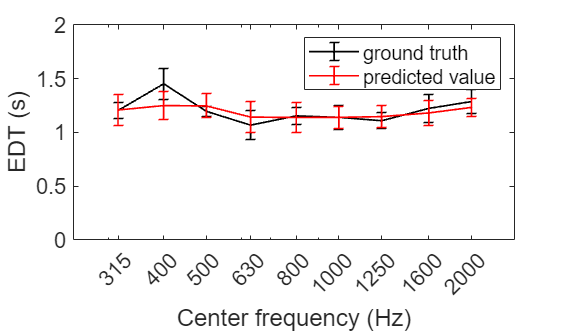

figure;
errorbar(centerFrequenciesValid,mean(EDTTruth),std(EDTTruth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(EDTPredicted),std(EDTPredicted), "r-", 'LineWidth', 1)
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');ylabel('EDT (s)');
plot_figures(250,2500,0, 2)

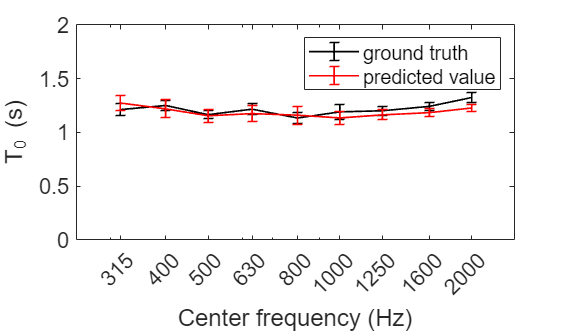

figure;
errorbar(centerFrequenciesValid,mean(T20Truth),std(T20Truth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(T20Predicted),std(T20Predicted), "r-", 'LineWidth', 1)
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');ylabel('T_2_0 (s)');
plot_figures(250,2500,0, 2)

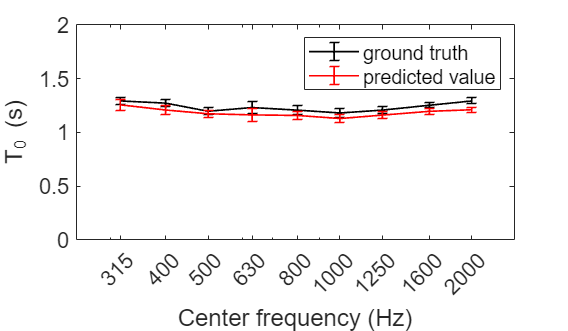

figure;
errorbar(centerFrequenciesValid,mean(T30Truth),std(T30Truth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(T30Predicted),std(T30Predicted), "r-", 'LineWidth', 1)
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');ylabel('T_3_0 (s)');
plot_figures(250,2500,0, 2)

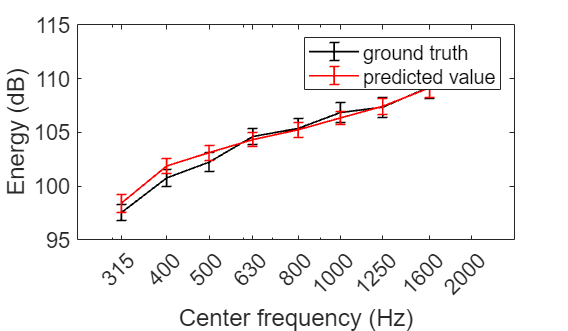

figure;
errorbar(centerFrequenciesValid,mean(EnergyTruth),std(EnergyTruth), "k-", 'LineWidth', 1)
hold on
errorbar(centerFrequenciesValid,mean(EnergyPredicted),std(EnergyPredicted), "r-", 'LineWidth', 1)
set(gca,'XScale','log');
legend('ground truth','predicted value')
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');ylabel('Energy (dB)'); 
plot_figures(250,2500,95, 115)

## To check scattering degree in the predicted sound field

#### To calculate ESCs

% Empty room IRs
IRfiltered_P(1,:,:,:)=IRfiltered(1,:,:,:);
% Predicted furnished room IRs
IRfiltered_P(2,:,:,:)=IRfilteredFurnishedPredicted;
% To calculate ESCs of this predicted sound fields
[ESC_P] = calculate_ESC(fs,maxOrder,nOrder,nScenarios,nReceivers,nOctaveBands,nChoppedIR,nFrequency,IRfiltered_P);

####  Plot ESC     [FIG.14]

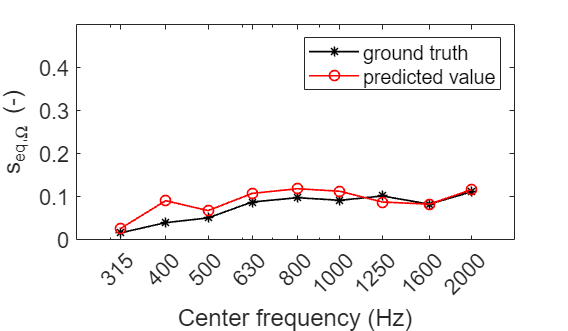

figure;
plot(centerFrequenciesValid, ESC, "k*-", 'LineWidth', 1)
hold on
plot(centerFrequenciesValid, ESC_P, "ro-", 'LineWidth', 1)
legend('ground truth','predicted value')
set(gca,'XScale','log');
xticks(centerFrequenciesValid)
xlabel('Center frequency (Hz)');
ylabel('s_{eq,\Omega} (-)');
plot_figures(250,2500,0, 0.5)

### Wide band IRs of furnished room

% Wide band Ground truth IRs
IRsWideBand=reshape(sum(IRfiltered,3),nScenarios,nReceivers,nSamplesSignal);
IRsFurnished.GroundTruth=reshape(IRsWideBand(2,:,:),nReceivers,nSamplesSignal)';
% Wide band predicted IRs
IRsFurnished.Predict=reshape(sum(IRfilteredFurnishedPredicted,2),nReceivers,nSamplesSignal)';
% save('IRsFurnished.mat', "IRsFurnished","receiverPos","sourcePos","volume","surfaceArea")